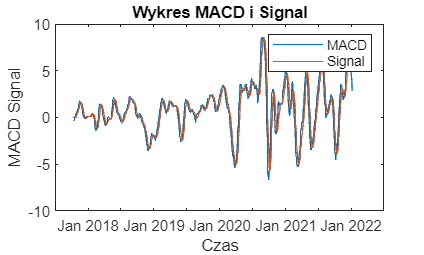

data = readtable('MACDiSignal.csv','Delimiter',';','Format','%{yyyy-MM-dd}D%f%f');

plot(data{:,1}, data{:,2},'DisplayName','MACD');
hold on
plot(data{:,1}, data{:,3},'DisplayName','Signal');
hold off

title('Wykres MACD i Signal')
xlabel('Czas')
ylabel('MACD Signal')
legend('MACD','Signal')
set(gcf,'Position',[100,100,1200,720])
set(gcf, 'PaperPositionMode', 'auto')
saveas(gcf,'MACD.png')


data_1 = readtable('Dane_in.csv','Delimiter',';','HeaderLines', 1,'Format','%{yyyy-MM-dd}D%f%f%f%f%f');

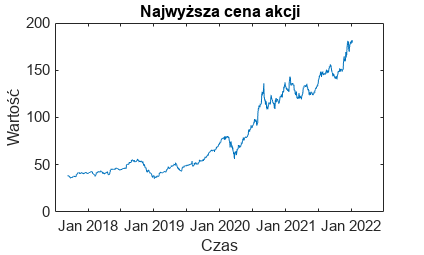


plot(data_1{:,1}, data_1{:,3});

title("Najwyższa cena akcji");
xlabel('Czas');
ylabel('Wartość');
set(gcf,'Position',[100,100,1200,720])
set(gcf, 'PaperPositionMode', 'auto')
saveas(gcf,"Wykres_ceny.png")